# **IO424 - LVDT Measurement**

This example shows how to set up the IO424 module for LVDT/RVDT (Linear Variable Differential Transformers/Rotary Variable Differential Transformers) measurements. The LVDT/RVDT signal is generated by the IO107 analog output module. The signal can however be generated in other ways, for example, using LVDT generators or an actual LVDT.

The IO424 is a 4-channel, 16-bit, LVDT/RVDT/Resolver/Synchro converter module. This module only has read capabilities, but can generate the excitation reference signal for Resolver and LVDT/RVDT.

## Setup

### Prerequisites

You will require at least the following to run this example:

- Speedgoat real-time target machine with one IO424 I/O module (non-Synchro version) installed

- Connector cable (50-pin MDR) from the IO424 module to the terminal board

- 50-pin MDR terminal board with jumper wires

Optional:

- One [IO107 I/O module](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io107) installed

- Connector cable (68-pin SCSI) from the IO107 module to the terminal board

- 68-pin SCSI terminal board with jumper wires

### How LVDT/RVDT Works

LVDTs and RVDTs are fundamentally the same type of electrical transformer, designed to measure displacement. Their distinction lies solely in the nature of the displacement: linear for LVDTs and angular for RVDTs. Due to this shared operational principle, the following explanations will focus on LVDTs, with the understanding that they are directly applicable to RVDTs.

LVDTs use an electromagnetic coupling to determine the linear displacement of a ferromagnetic core, which is mechanically linked to the object being measured. 

A typical LVDT sensor consists of a cylindrical structure housing three solenoid windings: a central primary winding and two symmetrically placed secondary windings. An alternating current applied to the primary winding induces a magnetic field, which in turn couples energy into the secondary windings via the core. The magnitude of the induced voltage in each secondary winding is directly proportional to the core's position. By calculating the difference or ratio of the voltages induced in the two secondary windings, the core's displacement (stroke) can be precisely determined. The secondary windings are configured to produce a 180-degree phase difference, enabling accurate directional displacement measurement.

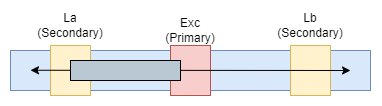

#### 6-Wire Ratiometric Wiring

This example utilizes a ratiometric, 6-wire configuration, which is set in the[ IO424 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io424_setup) block. However, the IO424 is also capable of reading 5-wire ratiometric and 4-wire differential LVDT signals.

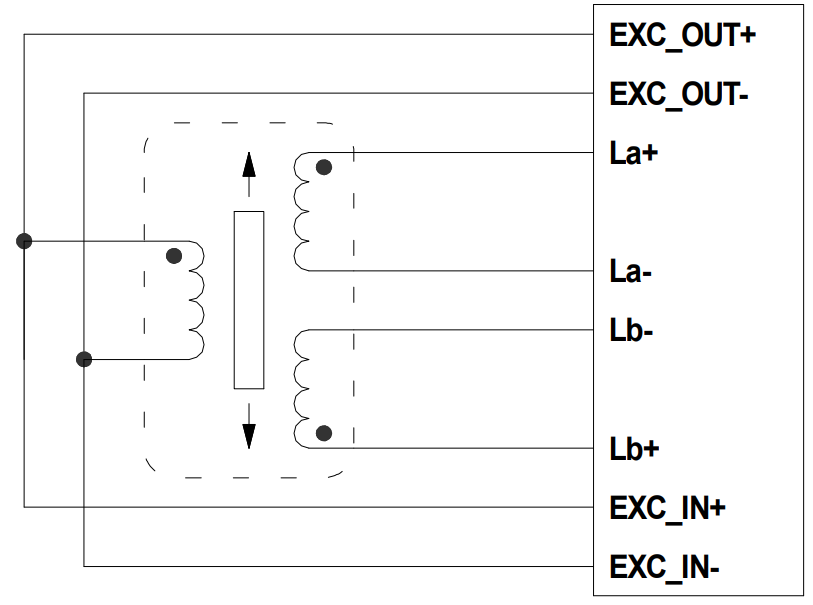

### Test Setup

Because the IO424 is designed for signal measurement, the LVDT excitation signal must be provided by an external source. In this example, the IO107 module is used, leveraging its DMA capability to achieve higher sampling rates.

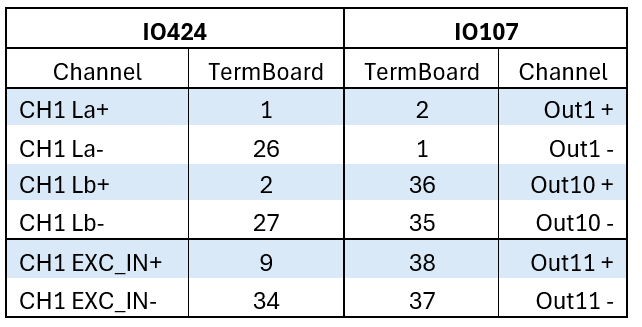

The full pin mapping of the IO424 can be found here: [IO424 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io424_pin_mapping)

## Model Description

### LVDT Signal Generation

The model's signal generation section, located on the left, uses three [Sine Wave](https://mathworks.com/help/dsp/ref/sinewave.html) blocks from the [DSP System Toolbox](https://www.mathworks.com/help/dsp/index.html) to create sampled sinusoidal signals. Each block generates a frame of 450 elements, enabling the IO107's Direct Memory Access (DMA) capability for high-speed signal output. One Sine Wave block generates a 4 VRMS, 1 kHz reference signal. This reference signal is then modulated by two lower-frequency (10 Hz) sinusoidal signals: a sine wave and a cosine wave, both with amplitudes ranging from 0 to 1 (achieved by an amplitude of 0.5 and a +0.5 offset). The resulting modulated signals, designated La and Lb, represent the LVDT excitation signals. To prevent zero-crossing issues, a small positive offset of +0.001 is added to the 10 Hz sine and cosine waves.

If no Speedgoat analog output module is available, alternative signal generation methods can be employed. This includes using external signal generators or a separate Simulink model containing continuous Sine Wave generators. The latter allows for signal data extrapolation, which can be used to generate CSV files for external signal generators. Finally, an actual LVDT sensor can be used as the signal source.

### LVDT Signal Reading

The right side of the model implements the LVDT signal acquisition and processing. In the[ IO424 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io424_setup) block, the input range is configured to optimally match the generated signal levels. Each channel, in this case a single channel, provides two output ports: Stroke and Status. The Stroke port outputs a single numerical value representing the measured displacement. The Status port outputs a seven-element vector, where each element corresponds to a specific error bit. For diagnostic purposes, the status bits are extracted with a [Demux block](https://mathworks.com/help/simulink/slref/demux.html), to access individual error bits.

## Open Simulink Model

 
modelName = 'sgMdl_IO424_LVDTMeasurementTest';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

The figure below shows the generated signals of the simulated LVDT:

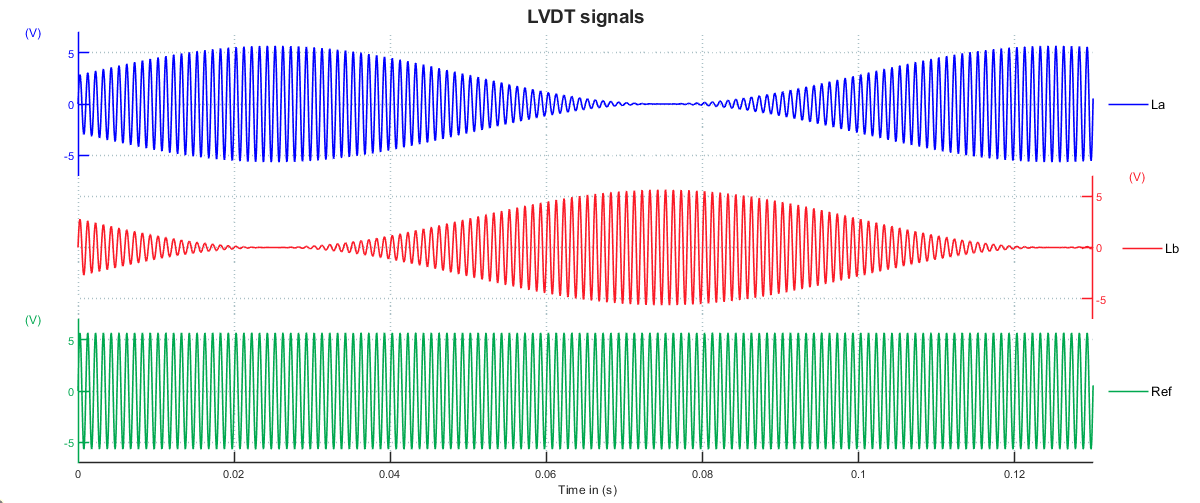

A zoom on the generated LVDT signals:

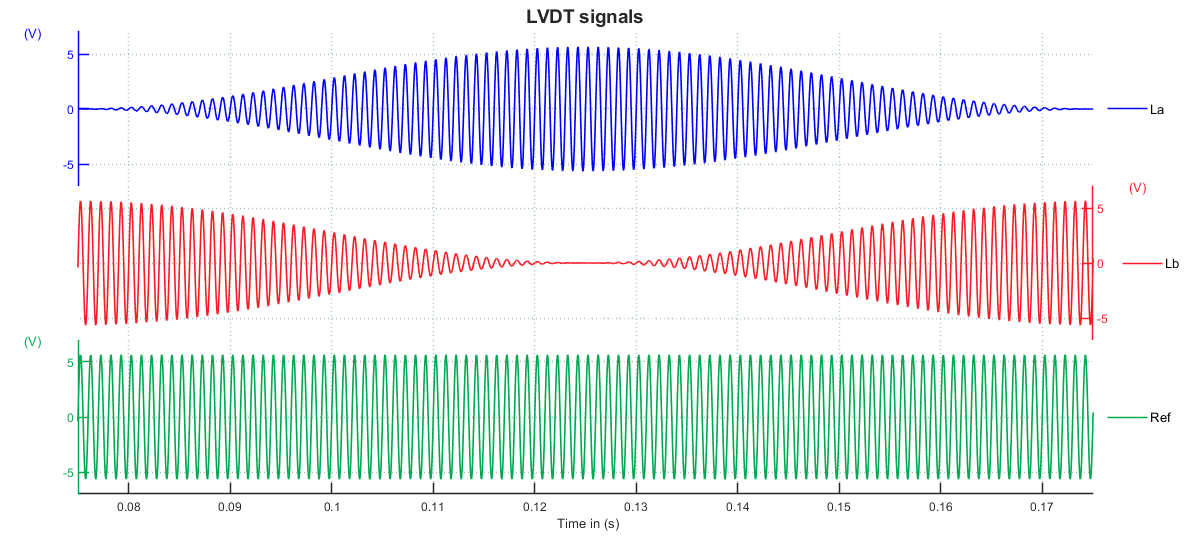

The readings align with what was configured in the LVDT signal generation. The stroke goes from -100 % to +100 % in a sinusoidal wave with a period of 100 ms, so 10 Hz. No errors were introduced in this example, so all the status bits stay at zero.

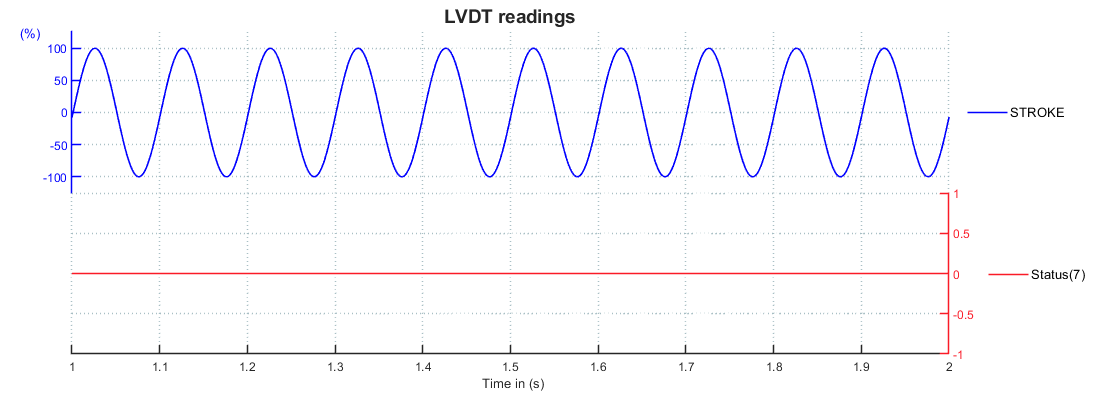

## Additional References

- [IO424 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io424)